Download Data

downloadURL  = "https://github.com/AprilRobotics/apriltag-imgs/archive/master.zip";
dataFolder   = fullfile(tempdir,"apriltag-imgs",filesep); 
options      = weboptions('Timeout', Inf);
zipFileName  = fullfile(dataFolder,"apriltag-imgs-master.zip");
folderExists = exist(dataFolder,"dir");

% Create a folder in a temporary directory to save the downloaded file.
if ~folderExists  
    mkdir(dataFolder); 
    disp("Downloading apriltag-imgs-master.zip (60.1 MB)...") 
    websave(zipFileName,downloadURL,options); 
    
    % Extract contents of the downloaded file.
    disp("Extracting apriltag-imgs-master.zip...") 
    unzip(zipFileName,dataFolder); 
end

` Generate the calibration pattern using AprilTags.`

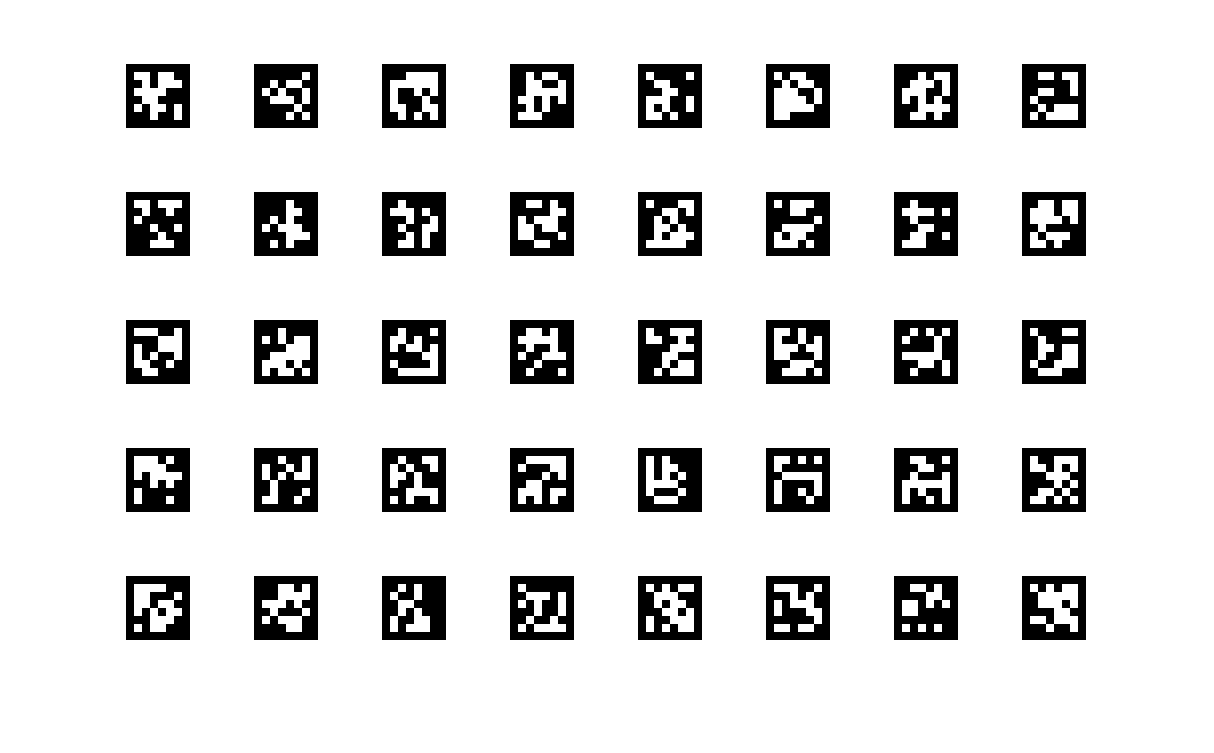

% Set the properties of the calibration pattern.
tagArrangement = [5,8];
tagFamily = "tag36h11";

% Generate the calibration pattern using AprilTags.
tagImageFolder = fullfile(dataFolder,"apriltag-imgs-master",tagFamily);
imdsTags = imageDatastore(tagImageFolder);
calibPattern = helperGenerateAprilTagPattern(imdsTags,tagArrangement,tagFamily);

Corner Detection

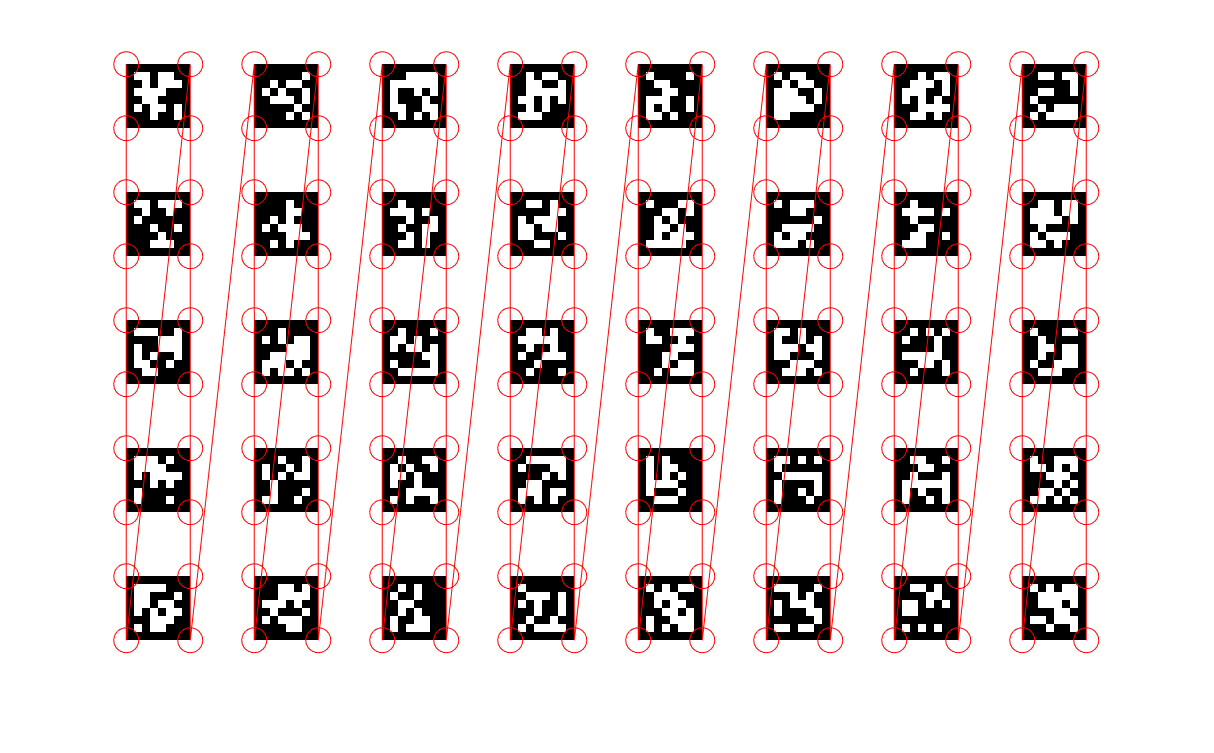

% Read and localize the tags in the calibration pattern.
[tagIds, tagLocs] = readAprilTag(calibPattern,tagFamily);

% Sort the tags based on their ID values.
[~, sortIdx] = sort(tagIds);
tagLocs = tagLocs(:,:,sortIdx);

% Reshape the tag corner locations into an M-by-2 array.
tagLocs = reshape(permute(tagLocs,[1,3,2]),[],2);

% Convert the AprilTag corner locations to checkerboard corner locations.
checkerIdx = helperAprilTagToCheckerLocations(tagArrangement);
imagePoints = tagLocs(checkerIdx(:),:);

% Display corner locations.
figure; imshow(calibPattern); hold on
plot(imagePoints(:,1),imagePoints(:,2),"ro-",MarkerSize=15)

Detect and localize april tags in real life

% Create an imageDatastore object to store the captured images.
imdsCalib = imageDatastore("E:/Omar 3amora/6- Graduation Project/Modules/Perception/2- Camera Callibration/ChAruco_Images_Path");

% Detect the calibration pattern from the images.
[imagePoints,boardSize] = helperDetectAprilTagCorners(imdsCalib,tagArrangement,tagFamily);

% Generate world point coordinates for the pattern.
tagSize = 16; % in millimeters
worldPoints = generateCheckerboardPoints(boardSize, tagSize);

Estimate camera parameters

% Determine the size of the images.
I = readimage(imdsCalib,1);
imageSize = size(I,1:2);

% Estimate the camera parameters.
params = estimateCameraParameters(imagePoints,worldPoints,ImageSize=imageSize);

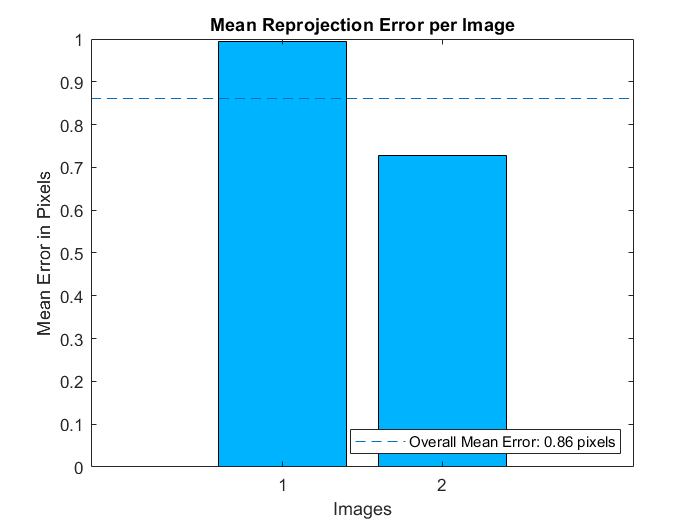

% Display the reprojection errors.
figure
showReprojectionErrors(params)

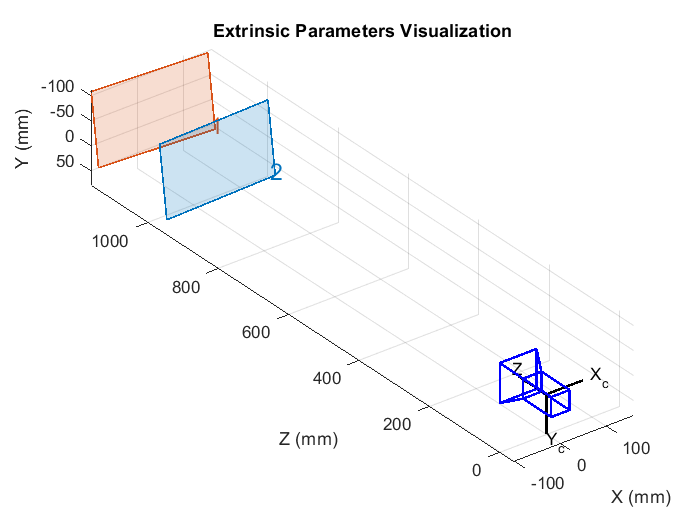

% Display the extrinsics.
figure
showExtrinsics(params)

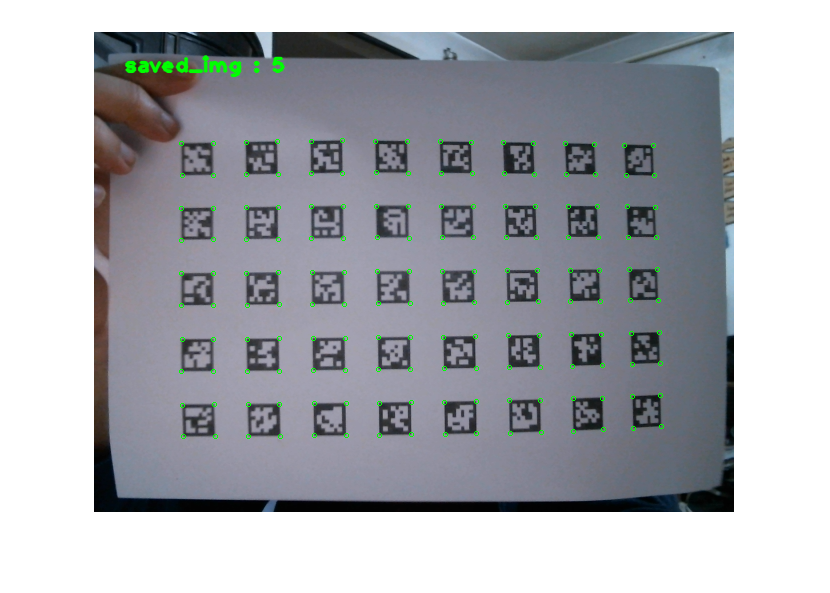

% Read a calibration image.
I = readimage(imdsCalib,2);

% Insert markers for the detected and reprojected points.
I = insertMarker(I,imagePoints(:,:,2),"o",Size=2);

% Display the image.
figure
imshow(I)

Function Helper

function calibPattern = helperGenerateAprilTagPattern(imdsTags,tagArragement,tagFamily)

numTags = tagArragement(1)*tagArragement(2);
tagIds = zeros(1,numTags);

% Read the first image.
I = readimage(imdsTags,3);
Igray = im2gray(I);

% Scale up the thumbnail tag image.
Ires = imresize(Igray,15,"nearest");

% Detect the tag ID and location (in image coordinates).
[tagIds(1), tagLoc] = readAprilTag(Ires,tagFamily);

% Pad image with white boundaries (ensures the tags replace the black
% portions of the checkerboard).
tagSize = round(max(tagLoc(:,2)) - min(tagLoc(:,2)));
padSize = round(tagSize/2 - (size(Ires,2) - tagSize)/2);
Ires = padarray(Ires,[padSize,padSize],255);

% Initialize tagImages array to hold the scaled tags.
tagImages = zeros(size(Ires,1),size(Ires,2),numTags);
tagImages(:,:,1) = Ires;

for idx = 2:numTags
   
    I = readimage(imdsTags,idx + 2);
    Igray = im2gray(I);
    Ires = imresize(Igray,15,"nearest");
    Ires = padarray(Ires,[padSize,padSize],255);
    
    tagIds(idx) = readAprilTag(Ires,tagFamily);
    
    % Store the tag images.
    tagImages(:,:,idx) = Ires;
     
end

% Sort the tag images based on their IDs.
[~, sortIdx] = sort(tagIds);
tagImages = tagImages(:,:,sortIdx);

% Reshape the tag images to ensure that they appear in column-major order
% (montage function places image in row-major order).
columnMajIdx = reshape(1:numTags,tagArragement)';
tagImages = tagImages(:,:,columnMajIdx(:));

% Create the pattern using 'montage'.
imgData = montage(tagImages,Size=tagArragement);
calibPattern = imgData.CData;

end

function [imagePoints,boardSize,imagesUsed] = helperDetectAprilTagCorners(imdsCalib,tagArrangement,tagFamily)

% Get the pattern size from tagArrangement.
boardSize = tagArrangement*2 + 1;

% Initialize number of images and tags.
numImages = length(imdsCalib.Files);
numTags = tagArrangement(1)*tagArrangement(2);

% Initialize number of corners in AprilTag pattern.
imagePoints = zeros(numTags*4,2,numImages);
imagesUsed = zeros(1,numImages);

% Get checkerboard corner indices from AprilTag corners.
checkerIdx = helperAprilTagToCheckerLocations(tagArrangement);

for idx = 1:numImages

    % Read and detect AprilTags in image.
    I = readimage(imdsCalib,idx);
    [tagIds,tagLocs] = readAprilTag(I,tagFamily);

    % Accept images if all tags are detected.
    if numel(tagIds) == numTags
        % Sort detected tags using ID values.
        [~,sortIdx] = sort(tagIds);
        tagLocs = tagLocs(:,:,sortIdx);
        
        % Reshape tag corner locations into a M-by-2 array.
        tagLocs = reshape(permute(tagLocs,[1,3,2]),[],2);
        
        % Populate imagePoints using checkerboard corner indices.
        imagePoints(:,:,idx) = tagLocs(checkerIdx(:),:);
        imagesUsed(idx) = true; 

    end
    
end

end

function checkerIdx = helperAprilTagToCheckerLocations(tagArrangement)

numTagRows = tagArrangement(1);
numTagCols = tagArrangement(2);
numTags = numTagRows * numTagCols;

% Row index offsets.
rowIdxOffset = [0:numTagRows - 1; 0:numTagRows - 1];

% Row indices for first and second columns in board.
col1Idx = repmat([4 1]',numTagRows,1);
col2Idx = repmat([3 2]',numTagRows,1);
col1Idx = col1Idx + rowIdxOffset(:)*4;
col2Idx = col2Idx + rowIdxOffset(:)*4;

% Column index offsets
colIdxOffset = 0:4*numTagRows:numTags*4 - 1;

% Implicit expansion to get all indices in order.
checkerIdx = [col1Idx;col2Idx] + colIdxOffset;

end

function [originLabel,xLabel,yLabel] = helperDrawImageAxesLabels(boardSize,imagePoints)

    numBoardRows = boardSize(1)-1;
    numBoardCols = boardSize(2)-1;
    
    % Reshape checkerboard corners to boardSize shaped array
    boardCoordsX = reshape(imagePoints(:,1), [numBoardRows,numBoardCols]);
    boardCoordsY = reshape(imagePoints(:,2), [numBoardRows,numBoardCols]);
    boardCoords = cat(3, boardCoordsX,boardCoordsY);
    
    % Origin label (check if origin location is inside the image)
    if ~isnan(boardCoordsX(1,1))
        p1 = boardCoords(1,1,:);
        
        refPointIdx = find(~isnan(boardCoordsX(:,1)),2);
        p2 = boardCoords(refPointIdx(2),1,:);
        
        refPointIdx = find(~isnan(boardCoordsX(1,:)),2);
        p3 = boardCoords(1,refPointIdx(2),:);
        
        [loc, theta] = getAxesLabelPosition(p1,p2,p3);
        
        originLabel.Location = loc;
        originLabel.Orientation = theta;
    else
        originLabel = struct;
    end
    
    % X-axis label
    firstRowIdx = numBoardCols:-1:1;
    refPointIdx13 = find(~isnan(boardCoordsX(1,firstRowIdx)),2);
    refPointIdx13 = firstRowIdx(refPointIdx13);
    
    p1 = boardCoords(1,refPointIdx13(1),:);
    p3 = boardCoords(1,refPointIdx13(2),:);
    
    refPointIdx2 = find(~isnan(boardCoordsX(:,refPointIdx13(1))),2);
    p2 = boardCoords(refPointIdx2(2),refPointIdx13(1),:);
    
    [loc, theta] = getAxesLabelPosition(p1,p2,p3);
    theta = 180 + theta;
    
    xLabel.Location    = loc;
    xLabel.Orientation = theta;
    
    % Y-axis label
    firstColIdx = numBoardRows:-1:1;
    refPointIdx12 = find(~isnan(boardCoordsX(firstColIdx,1)),2);
    refPointIdx12 = firstColIdx(refPointIdx12);
    
    p1 = boardCoords(refPointIdx12(1),1,:);
    p2 = boardCoords(refPointIdx12(2),1,:);
    
    refPointIdx3 = find(~isnan(boardCoordsX(refPointIdx12(1),:)), 2);
    p3 = boardCoords(refPointIdx12(1),refPointIdx3(2),:);
    
    [loc,theta] = getAxesLabelPosition(p1,p2,p3);
    
    yLabel.Location = loc;
    yLabel.Orientation = theta;
    
    %--------------------------------------------------------------
    % p1+v
    %  \
    %   \     v1
    %    p1 ------ p2
    %    |
    % v2 |
    %    |
    %    p3
    function [loc,theta] = getAxesLabelPosition(p1,p2,p3)
        v1 = p3 - p1;
        theta = -atan2d(v1(2),v1(1));
        
        v2 = p2 - p1;
        v = -v1 - v2;
        d = hypot(v(1),v(2));
        minDist = 40;
        if d < minDist
            v = (v / d) * minDist;
        end
        loc = p1 + v;
    end
    %--------------------------------------------------------------
    
end